# **Key Concepts in Blind Source Separation for Neuroscience**

Prof. Carina M Germer

UNIVERSIDADE ESTADUAL DE CAMPINAS

## Introduction to Blind Source Separation (BSS)

Blind Source Separation (BSS) is a fundamental and challenging problem in signal processing, where the goal is to recover original source signals from observed mixtures without prior knowledge of the sources or the mixing process. The term "blind" refers to the lack of information about both the source signals and the mixing system. BSS techniques are widely applicable in fields ranging from neuroscience (e.g., analyzing EEG or EMG signals) to audio processing (e.g., the famous "cocktail party problem").

**The Cocktail Party Problem**

Imagine you are at a lively cocktail party, surrounded by people engaged in various conversations. Multiple microphones placed around the room capture the mixed sound signals from different speakers. The challenge is to separate each person's speech from this mixture, despite not knowing how the sounds were mixed or where each speaker is located. This scenario exemplifies the BSS problem, where the source signals (individual voices) and the mixing system (room acoustics and microphone placements) are unknown.

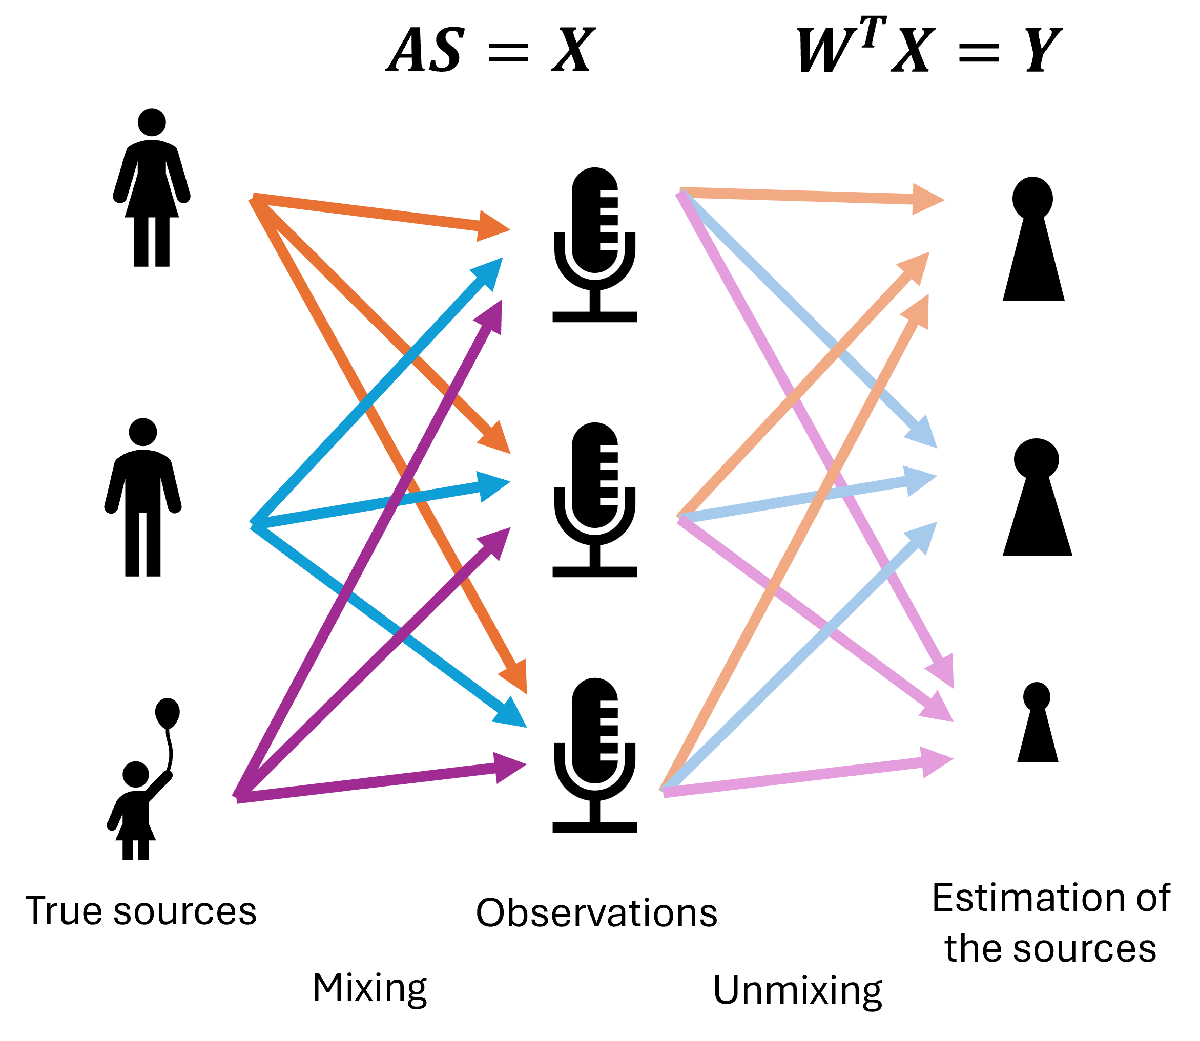

**Mathematical Formulation of BSS**

Mathematically, the BSS problem can be described as follows:

- **Source signals:** S (unknown) - the original signals we wish to recover.

- **Mixing matrix:** A (unknown) - the projection matrix, mixing matrix or transformation matrix

- **Observed signals:** X (known) - the signals recorded by sensors or microphones.

- **Separation matrix:** W (to be estimated) - the matrix used to separate the observed signals into estimated sources.

- **Estimated sources:** Y (to be estimated) - the signals we obtain after applying the separation matrix.

In practical terms, each observed signal $x_{i\;}$ can be thought of as a linear weighted combination of the source signals $s_j$:


$$x_i \left(k\right)=a_{i1} s_1 \left(k\right)+a_{i2} s_2 \left(k\right)+\ldotp \ldotp \ldotp +a_{\textrm{iM}} s_M \left(k\right)$$



$$\mathit{\mathbf{X}}\left(k\right)=\textrm{AS}\left(k\right)$$


Where $a_{\textrm{im}}$ represents the elements of the mixing matrix A.

In order to retrieve the sources, and considering that the mixing matrix is invertible, we have 


$$\overset{~}{\mathit{\mathbf{S}}} ={\mathit{\mathbf{A}}}^{-1} \mathit{\mathbf{X}}$$


Since we do not know the mixing matrix, the problem of BSS is to estimate the separation matrix W such that Y$\approx$S.


$$\mathbf{Y}={\mathit{\mathbf{W}}}^T \mathit{\mathbf{X}}$$


**Challenges in BSS**

The BSS problem is considered "ill-posed" because there are typically more sources (including noise) than sensors, making it difficult, if not impossible, to perfectly isolate each source. Even after separation, the sources may remain somewhat mixed, but the goal is to achieve a meaningful reduction in this mixing.

There are several indeterminacies in BSS:

- **Scale indeterminacy:** The variances (energies) of the source signals cannot be determined. We assume the sources have unit variance, but we cannot know if the estimated sources are scaled versions of the original sources.

- **Permutation indeterminacy:** The order of the sources cannot be determined. Any permutation of the sources is equally valid.

- **Non-invertibility of the mixing matrix:** When the number of sources exceeds the number of observations, the mixing matrix is not invertible, complicating the extraction of sources.

**Independent Component Analysis (ICA)**

ICA is one of the most popular and effective methods for solving BSS problems. ICA assumes that the source signals are statistically independent and non-Gaussian. The key idea is to find a linear transformation (or separate matrix) that maximizes the statistical independence of the estimated source signals.  

**Principal Component Analysis (PCA) **

Before diving into ICA, it's essential to understand Principal Component Analysis (PCA). PCA is a statistical technique that simplifies the data by reducing its dimensionality while preserving as much variance as possible. In the context of BSS, PCA can be used as a pre-processing step to decorrelate the observed signals and make the problem more tractable for ICA.

**Whitening**

Whitening is an important scaling step where the components are adjusted to have unit variance. This step ensures that each dimension contributes equally to the analysis and enhances the spatial selectivity and precision of the source separation. In the BSS context, whitening helps address the scale indeterminacy by standardizing the data before applying ICA.

### **Principal Component Analysis (PCA)**

PCA is a technique that essentially represents the structure of a dataset by capturing its** variance**. PCA views variance as a key indicator of significance, under the assumption that the directions in which the data varies the most are the most informative. The goal of PCA is to find a representation of the data with minimal redundancy by maximizing the decorrelation of the data. PCA does this by creating a weighted combination of channels such that the resulting component has maximal variance.

Consider a dataset with multiple variables, some of which may be highly correlated and thus provide similar information, while others capture unique aspects of the data. PCA analyzes the variances within the dataset to reveal the underlying structure and relationship between variables. Subsequently, dimensionality reduction can be applied to simplify the dataset while retaining its essential characteristics.

For example, let's consider a dataset with two sources (S1 and S2):


$$\begin{array}{l}
S_1 =\sin \left(t\right)\\
S_2 =0\ldotp 4\cdot \sin \left(t+\frac{\pi }{6}\right)
\end{array}$$
 

And a mixing matrix (H) that defines how the original sources are combined to create the observed data: 


$$\mathit{\mathbf{H}}=\left\lbrack \begin{array}{cc}
1\ldotp 5 & -1\ldotp 5\\
-0\ldotp 5 & 1\ldotp 0
\end{array}\right\rbrack$$


$\mathit{\mathbf{X}}=\mathit{\mathbf{H}}\mathit{\mathbf{S}}$    (1)

 The mixing matrix is imposing a strong negative correlation between the observed signals, as illustrated in the scatter plot of the mixed data. 

% simulation parameters
 

clear all
N = 1000; % time points
M = 2; % channels

% Time vector (radian units)
t = linspace(0, 6*pi, N);

% Define sources
source1 = sin(t); % First source
source2 = 0.4*sin(t+pi/6); % Second source
% source2 = 0.1*randn(1,N);

% Mixing matrix
mixing_matrix = [1.5, -1.5; -.5, 1.0]; % Example mixing matrix

% Generate mixed data
mixed_data = mixing_matrix * [source1; source2];


% Add noise to the mixed data
Data = mixed_data + 0.15 * randn(M, N);

% Plot the data
figure(), 

subplot(2,2,1), hold on
plot(t,source1)
plot(t,source2)
% set(gca,'ytick', 3:3:3*M, 'yticklabel', {'Ch1', 'Ch2'})
xlabel('Time (s)')
ylabel('Amplitude (au)')
title('Sources')
axis square

subplot(2,2,2), 
xlabel('Source 1')
ylabel('Source 2')
title('Scatter Plot of Sources')
hold on
origin=[0,0];
U = mixing_matrix(:, 1);  % X-components of arrows
V = mixing_matrix(:, 2);  % Y-components of arrows
% Plotting the arrows
quiver(origin(1), origin(2), U(1), V(1), 0, 'c', 'LineWidth', 1.5, 'MaxHeadSize', .5);
quiver(origin(1), origin(2), U(2), V(2), 0, 'c', 'LineWidth', 1.5, 'MaxHeadSize', .5);
scatter(source1, source2, 4, 'k', 'filled')
set(gca,'xlim',[-2 2],'ylim',[-2 2])
grid on
axis square

subplot(2,2,3), hold on
arrayfun(@(ii) plot(t, Data(ii,:) + 4*ii), 1:M)
set(gca,'ytick', 4:4:4*M, 'yticklabel', {'Ch1', 'Ch2'})
xlabel('Time')
title('Time Series Data')
axis square

subplot(2,2,4), scatter(Data(1,:), Data(2,:), 4, 'k', 'filled')
xlabel('x_{Ch1}')
ylabel('x_{Ch2}')
title('Scatter Plot of Mixed Data')
set(gca,'xlim',[-1 1]*max(Data(:)),'ylim',[-1 1]*max(Data(:)))
grid on
axis square

% Transpose data for output
arg = Data';

PCA uncover the underlyting structure of the data by identifying the directions—called **principal components**—where the data shows the most variation. These principal components are new axes that are orthogonal (uncorrelated) to each other, and they represent different aspects of the data's variance. The first principal component captures the direction of the greatest variance, the second captures the next greatest variance, and so on.

 

% mean-center
arg = arg - mean(arg,1);

% covariance matrix
covmat = arg'*arg / (length(arg)-1);

% eigendecomposition
[evecs,evals] = eig(covmat);
[evals,sidx] = sort(diag(evals),'descend');
evecs = evecs(:,sidx);

% Convert eigenvalues to %
Pevals = 100*evals/sum(evals);

% plot the eigenvectors on the data
% plot the data in a scatter plot
figure()
plot(arg(:,1),arg(:,2),'k.','markersize',7)
hold on
plot([0 evecs(1,1)],[0 evecs(2,1)],'m','linew',3)
plot([0 evecs(1,2)],[0 evecs(2,2)],'m','linew',1.5)
axis square
set(gca,'xlim',[-1 1]*max(arg(:)),'ylim',[-1 1]*max(arg(:)))
xlabel('x_{Ch1}')
ylabel('x_{Ch2}')
grid on
axis square

PCA identify the directions where the data varies the most by constructing the **covariance matrix **(R in Eq 2) of the dataset. The covariance matrix provides insights into how pairs of variables in the data are linearly related to each other. Each element in the covariance matrix represents the covariance between two variables, indicating how much these variables tend to increase or decrease together.

$\mathit{\mathbf{R}}=\frac{\left({\mathit{\mathbf{X}}}^T \mathit{\mathbf{X}}\right)}{N-1}$    (2)

Where Y is an NxM matrix, with N being the number of samples and M the number of channels.

By calculating the **eigenvectors** of the covariance matrix, we identify the directions in the data space - principal components - where the data exhibits the greatest variation, or, in other words, the directions along which the variance in the dataset is maximized. The corresponding **eigenvalues** indicate the amount of total variance captured by each principal component. Larger eigenvalues correspond to principal components that account for more of the dataset's variance. In summary, the eigenvectors reveal the key directions of variance in the data, while the eigenvalues quantify the significance of each of these directions.

This process is done by the eigen-decomposition (Eq 3):

$\textrm{RV}=\mathit{\mathbf{V}}\Lambda$  (3)

where V is the eigenvectors of R and $\Lambda$ is the diagonalized eigenvalue matrix of R.

By comparing each eigenvalue to the sum of all eigenvalues (which represents the total variance), we can determine the percentage of variance explained by each principal component. Note that most of the variance of the dataset is explained by component 1.

 
addpath(fullfile(pwd,'subfunctions'));

% show the covariance matrix
figure()
subplot(1,3,1)
imagesc(covmat), axis square
set(gca,'clim',[-1 1],'xtick',1:2,'ytick',1:2)
xlabel('Channels'), ylabel('Channels')
colormap(redblue)
colorbar()
title('Covariance Matrix')
axis square

% plot eigenvectors
subplot(1,3,2)
imagesc([0,0;0,0]), axis square
for a=1:2
    for b=1:2
        text(b-0.25,a,num2str(evecs(a,b),'%1.2f'));
    end
end
title('Eigenvectors')
set(gca,'xtick',0.5:1:2.5,'xticklabel',[],'ytick',0.5:1:2.5,'yticklabel',[])
grid on
axis square

subplot(1,3,3)
plot(Pevals,'-ko')
for ii=1:2
    text(ii+0.2,Pevals(ii),num2str(evals(ii),'%1.2f'));
end
xlabel('Component')
ylabel('Percent Variance')
xlim([0.5 2.5])
set(gca,'xtick',1:2)
title('Normalized Eigenvalues')
axis square


To compute the **component** time series in PCA (or principal component scores), you project the original data onto the eigenvectors (principal components). Therefore, PCA reorients the data along new axes. This gives you a new set of variables that represent the data in terms of its most significant patterns of variation over time.

$X^{\textrm{PCA}} =\textrm{VX}$  (4)

 
% rotate PCA
xPCA = arg * evecs;

figure()
subplot(1,2,1)
plot(xPCA(:,1),xPCA(:,2),'k.','markersize',7)
set(gca,'xlim',[-1 1]*max(arg(:)),'ylim',[-1 1]*max(arg(:)))
xlabel('x_1^{PCA}')
ylabel('x_2^{PCA}')
axis square
grid on
title ('PC space')

subplot(1,2,2), hold on
plot(t,xPCA(:,1))
plot(t,xPCA(:,2))
xlabel('time')
title('Component time series')
axis square


The PCA transformation is powerful because it enables us to represent data in a more compact form, reducing the number of variables (or dimensions) while preserving most of the dataset's original variance. However, as illustrated in the figure above, the component scores do not perfectly capture the original sources. This limitation means that PCA is generally not effective for source separation unless the sources are already orthogonal in the data space. Nevertheless, PCA serves as an excellent pre-processing tool for ICA, as it decorrelates the observed signals, thereby simplifying the source separation problem.

#### Whitening

Whitening is a preprocessing step similar to PCA, but it goes further by not only decorrelating the signals but also scaling them to have **unit variance**. By standardizing the data, the whitening process ensures that each dimension contributes equally to the analysis, thereby improving the spatial selectivity and precision of the components, which is particularly valuable in applications like ICA. 

By taking the PCA steps described before, we only need to normalize the components by its variance, which is given by the diagonalized eigenvalue matrix or R ($\Lambda$, from Eq 3). 

${\mathit{\mathbf{X}}}^{\textrm{white}} =\textrm{WX}=\left(\mathit{\mathbf{V}}\Lambda^{-\frac{1}{2}} {\mathit{\mathbf{V}}}^T \right)\mathit{\mathbf{X}}=\Lambda^{-\frac{1}{2}} {\mathit{\mathbf{X}}}^{\textrm{PCA}}$    (5)

We can say then that whitening is PCA with variance normalization.

 

% Compute the whitening matrix
whitening_matrix = evecs * diag(1 ./ sqrt(evals)) * evecs';

% Apply the whitening transformation 
yWhit = arg * whitening_matrix;


figure()
subplot(1,2,1)
plot(yWhit(:,1),yWhit(:,2),'k.','markersize',7)
set(gca,'xlim',[-1 1]*max(yWhit(:)),'ylim',[-1 1]*max(yWhit(:)))
xlabel('x_1^{White}')
ylabel('x_2^{White}')
axis square
title ('PC space')

subplot(1,2,2), hold on
plot(t,yWhit(:,1))
plot(t,yWhit(:,2))
xlabel('time')
title('Component time series')
axis square

#### **Exploring PCA in a 2-D problem:**

This simulation demonstrates how PCA operates on synthetic 2D datasets. The code creates two sets of signals derived from a sine wave source and noise, selectable via the 'Signal' drop-down menu. The Signal-to-Noise ratio can be adjusted using the 'SignalNoiseRatio' slider. The simulation then rotates the signals to introduce correlations, with the angle of rotation controlled by the 'Angle' slider. Additionally, offset components can be added to the mixed signal through the 'Offset_Ch1' and 'Offset_Ch2' variables. You can also choose whether to mean-center or whiten the data by selecting the 'MeanCenter' and 'Whiten' checkboxes. The process involves calculating the covariance matrix, performing eigen decomposition, applying whitening, and identifying the principal components.

Use the simulation menu below to explore and answer the following questions:

**Questions:**

- Why is it crucial to mean-center the data?

- What is the effect of whitening in the principal component space?

- Why aren’t all the diagonal elements of the covariance matrix equal to one?

- What determines the mixing matrix in this simulation?

- What can you infer about the distribution in the principal component space when the correlation angle is zero? And at 90º?

- How does changing the correlation between variables affect the covariance matrix, eigenvectors and eigenvalues?

- How does changing the Signal-to-Noise Ratio affect the covariance matrix, eigenvectors and eigenvalue?

- How does PCA handle noise in the data, and what impact does it have on the principal components?

- What insights can be gained by examining the eigenvalues of the covariance matrix?

- What are the limitations of PCA when dealing with non-linear relationships in the data?

- What do you expect the covariance matrix of the components to look like?

- Why might PCA not provide an accurate estimation of the sources?

 
Signal2 = false;
SignalNoiseRatio = 19 ;

N = 1000;
t = linspace(0,4*pi,N)';

source1 = sin(t);
source2 = sin(2*t);

arg = [source1, randn(N,1)/SignalNoiseRatio]; 
xx = [source2, randn(N,1)/SignalNoiseRatio]; 

% rotation matrix
Angle = 120;
th = pi*(-Angle)/180;
R1 = [ cos(th) -sin(th); sin(th) cos(th) ];
th2 = pi*(-Angle+30)/180;
R2 = [ cos(th2) -sin(th2); sin(th2) cos(th2) ];

% add offset
Offset_Var1 = -1;
Offset_Var2 = 1;
MeanCenter = true;
Whitening = false;

%rotate
% y = Rsource*R1;
arg = arg*R1;
yy = xx*R2;

if Signal2; arg=[arg;yy]; end

arg = arg + [Offset_Var1, Offset_Var2];

% mean-center
if MeanCenter; arg = arg - mean(arg,1); end

% covariance matrix
covmat = arg'*arg / (length(arg)-1);

% eigendecomposition
[evecs,evals] = eig(covmat);
[evals,sidx] = sort(diag(evals),'descend');
evecs = evecs(:,sidx);

if Whitening
    % Compute the whitening matrix
    whitening_matrix = evecs * diag(1 ./ sqrt(evals)) * evecs';
    % Apply the whitening transformation
    xPCA = arg * whitening_matrix;
else
    % Rotate PCA
    xPCA = arg * evecs;
end

% Convert eigenvalues to %
Pevals = 100*evals/sum(evals);

% plot data
figure()

subplot(3,2,1), hold on
plot(arg(:,1),arg(:,2),'k.','markersize',7)
plot([0 evecs(1,1)],[0 evecs(2,1)],'m','linew',3)
plot([0 evecs(1,2)],[0 evecs(2,2)],'m','linew',1)
set(gca,'xlim',[-1 1]*max(abs(arg(:))),'ylim',[-1 1]*max(abs(arg(:))))
xlabel('Ch 1'), ylabel('Ch 2')
axis square
title ('Data space')
grid on


subplot(3,2,2), hold on
plot(xPCA(:,1),xPCA(:,2),'k.','markersize',7)
set(gca,'xlim',[-1 1]*max(abs(xPCA(:))),'ylim',[-1 1]*max(abs(xPCA(:))))
xlabel('PC_1'), ylabel('PC_2')
axis square
title ('PC space')
grid on


% plot eigenvectors
subplot(3,5,[6,7])
imagesc([0,0;0,0]), axis square
for a=1:2
    for b=1:2
        text(b-0.25,a,num2str(evecs(a,b),'%1.2f'));
    end
end
title('Eigenvectors')
set(gca,'xtick',0.5:1:2.5,'xticklabel',[],'ytick',0.5:1:2.5,'yticklabel',[])
grid on

subplot(3,5,8)
imagesc([0;0])
for b=1:2
    text(1-0.25,b,num2str(evals(b),'%1.2f'));
end
title('Eigenvalues')
set(gca,'xtick',0.5:1:1.5,'xticklabel',[],'ytick',0.5:1:1.5,'yticklabel',[])
grid on

% plot covmat
subplot(3,5,[9,10])
imagesc(covmat), axis square
set(gca,'clim',[-1 1],'xtick',1:2,'ytick',1:2)
xlabel('Channels'), %ylabel('Channels')
colormap(redblue)
title('Covariance Matrix')
colorbar


subplot(3,5,11:15)
plot(xPCA)
ylabel('Sample')
xlabel('Amplitude (au)')
title('Components')

CovComponents = xPCA'*xPCA/(length(xPCA)-1)

#### **PCA on Experimental Data**

The dataset is an EEG recording of event related potential with 64 channels.

 
close all; clear, clc

currentFolder = pwd;
addpath(fullfile(pwd,'subfunctions'));
addpath(fullfile(pwd,'data'));

%% load data
load simpleEEGdata.mat
% load sampleEEGdata.mat
EEG.data = double( EEG.data );

fprintf('done!')

  
SSE=[-1000;1500];

ChannelSelection1 = 19;
ChannelSelection2 = 12;
ChannelSelection3 = 50;

Whitening = false;

SelectStart = SSE(1);
SelectEnd = SSE(2);

% cut data
[~,iInit]=min(abs(EEG.times-SelectStart));
[~,iEnd]=min(abs(EEG.times-SelectEnd));
EEGC.data = EEG.data(:,iInit:iEnd,:);
EEGC.times = EEG.times(:,iInit:iEnd,:);

%% compute PCA
% average data, mean-centre, covariance
Data  = EEGC.data;
% erp  = mean(EEGC.data,3);
Data = Data - mean(Data,2);
covd = Data*Data'/(size(EEGC.data,2)-1);

% eig and sort
[evecs,evals] = eig( covd );
[evals,sidx] = sort(diag(evals),'descend');
evecs = evecs(:,sidx);

% Compute the whitening matrix
whitening_matrix = evecs * diag(1 ./ sqrt(evals)) * evecs';
evals = 100*evals/sum(evals);

% Apply the whitening transformation 
if Whitening 
    DataW = whitening_matrix *Data;
else 
    DataW = Data; 
end

% principal components time series
pc_timeseries = evecs(:,1:2)'*DataW;


%% ----------------------------------------------
% plot PC results in time-voltage space
figure(1), clf

% plot time series
subplot(311)
plot(EEGC.times,Data([ChannelSelection1 ChannelSelection2 ChannelSelection3],:),'linew',1.5 )
% plot(EEGC.times,mean(erp([19 32 20],:),1)*5,'linew',1.5 )
ylabel('Amplitude (mV)')
title('Time series data')
xlabel('Time (ms)')
hold on
plot(repmat([-1000;-400;0;250;500;800;1500],[1,2]),[-5 10],':k')
legend({sprintf('Ch%d',ChannelSelection1);sprintf('Ch%d',ChannelSelection2);sprintf('Ch%d',ChannelSelection3)})

% eigenspectrum
subplot(337)
plot(evals(1:20),'ko-','markerfacecolor','w','linew',1.5,'markersize',4)
title('Eigenspectrum'), axis square
ylabel('Percent variance'), xlabel('Component number')

% topographical map of first eigenvector
subplot(338)
topoplotIndie(evecs(:,1),EEG.chanlocs,'numcontour',0,'shading','interp','electrodes','numbers');
title('PC1 topomap')

subplot(339)
topoplotIndie(evecs(:,2),EEG.chanlocs,'numcontour',0,'shading','interp','electrodes','numbers');
title('PC2 topomap')


% plot time series
subplot(312)
plot(EEGC.times,pc_timeseries,'linew',1.5 )
xlabel('Time (ms)')
ylabel('Amplitude (au)')
title('Component time series')
hold on
plot(repmat([-1000;-400;0;250;500;800;1500],[1,2]),[min(pc_timeseries(:)) max(pc_timeseries(:))]*1.1,':k')
legend({'PC1';'PC2'})

## **Independent Component Analysis (ICA)**

The BSS problem involves finding a separation matrix (${\mathit{\mathbf{W}}}^T$) that alows for the estimation of the original source signals from observed mixtures, such that $\mathbf{Y}={\mathit{\mathbf{W}}}^T \mathit{\mathbf{X}}$. This problem is inheritently complex and often ill-posed, presenting indeterminances in finding the separation matrix. However, as we've discussed, the whitening step simplifies this challenge by enforcing an orthogonality constraint on the separation matrix, which requires estimating fewer independent parameters, and by standardizing the variance to one, which is a fundamental assumtion of BSS problems. Consequently, after whitening, ICA only needs to find the orthogonal matriz (${\mathit{\mathbf{B}}}^T$) to successfully separate the independent components, such that $\hat{\mathit{\mathbf{Y}}} ={\mathit{\mathbf{B}}}^T {\mathit{\mathbf{X}}}^{\textrm{White}}$.  

While PCA focuses on maximizing the variance (i.e., the covariance of the components) under the assumption that "variance indicates relevance", ICA targets maximizing** statistical independence** between components. Before diving into the methods used to identify the separation matrix, it's crucial to understand the relationship between statistical independence and non-Gaussianity. Use the simulation menu below to explore this relationship and answer the following questions:

clear all; clc
addpath(fullfile(pwd,'subfunctions'));
addpath(fullfile(pwd,'data'));

% Parameters
fs = 1000;  % Sampling frequency (Hz)
 
t = 0:1/fs:1-1/fs;  % Time vector (1 second)


% Generate different sources
% rng(10)
% sine_wave = sin(2*pi*10*t);  % Sine wave (10 Hz)
% pulse_train = square(2*pi*5*t, 50);  % Pulse train (5 Hz, 50% duty cycle)
% triangle_wave = sawtooth(2*pi*7*t, 0.5);  % Triangle wave (7 Hz)
% eeg_signal = 0.5*sin(2*pi*8*t) + 0.3*sin(2*pi*13*t) + 0.1*randn(size(t));  % Simulated EEG signal

freq_range = [2, 10]; % Range for random frequencies (Hz)
phase_range = [0, 2*pi]; % Range for random phase shifts (radians)
amplitude_range = [0.3, 1]; % Range for random amplitude

NumbSources=1000;

frequency = arrayfun(@(x) freq_range(1) + (freq_range(2) - freq_range(1)) * rand,1:NumbSources);
phase_shift = arrayfun(@(x) phase_range(1) + (phase_range(2) - phase_range(1)) * rand, 1:NumbSources);
amplitude = arrayfun(@(x) amplitude_range(1) + (amplitude_range(2) - amplitude_range(1)) * rand, 1:NumbSources);

arg=arrayfun(@(n) 2*pi*frequency(n)*t*amplitude(n)+phase_shift(n),1:NumbSources,'UniformOutput',false);

Sine = cellfun(@(x) sin(x),arg,'Uni',0);
Pulse = cellfun(@(x) square(x,50),arg,'Uni',0);
Sawtooth = cellfun(@(x) sawtooth(x,0.2),arg,'Uni',0);
rands = 2*rand(NumbSources,length(t))-1;
Random = num2cell(rands,2)';

% simulate EEG
EEG_F1 = arrayfun(@(n) sin(2*pi*10*t+2*phase_shift(n)),1:NumbSources,'UniformOutput',false);
EEG_F2 = arrayfun(@(n) 0.5*sin(2*pi*30*t+phase_shift(n)),1:NumbSources,'UniformOutput',false);
EEG_F3 = arrayfun(@(n) 0.5*sin(2*pi*5*t+phase_shift(n)),1:NumbSources,'UniformOutput',false);
EEG = arrayfun(@(n) EEG_F1{n}+EEG_F2{n}+EEG_F3{n} + 0.1*randn(size(t)),1:NumbSources,'Uni',0); % Simulated EEG signal

% simulate pulse trains-------------------
medfrequency_range = [20,40];
covisi_range = [5, 8];

pulsefrequency = arrayfun(@(x) medfrequency_range(1) + (medfrequency_range(2) - medfrequency_range(1)) * rand,1:NumbSources);
CoVISI = arrayfun(@(x) covisi_range(1) + (covisi_range(2) - covisi_range(1)) * rand, 1:NumbSources);

% Calculate the median ISI (Interspike Interval)
medianISI = 1 ./ pulsefrequency; % Median ISI (seconds)

% Number of pulses to generate
numPulses = round(pulsefrequency);

% Generate ISIs with desired Cov
ISI_std = CoVISI .* medianISI;   % Standard deviation of ISIs
ISIs = arrayfun(@(i) abs(medianISI(i) + ISI_std(i) .* randn(1, numPulses(i))),1:NumbSources,'Uni',0);

% Generate pulse times from ISIs
pulseTimes = cellfun(@(i) cumsum(i),ISIs,'Uni',0); % Cumulative sum of ISIs gives pulse times

pulseSamples = cellfun(@(i) round(i*fs),pulseTimes,'Uni',0);

% Generate pulse train signal
PulseTrains = zeros(length(t),NumbSources);
for s=1:NumbSources
    for i = 1:length(pulseTimes{s})
        if pulseSamples{s}(i) <= fs
            PulseTrains(max(pulseSamples{s}(i),1),s) = 1; % Set the pulse at this time
        end
    end
end
PulseTrains = num2cell(PulseTrains',2)';

fprintf('done!')

**Questions:**

- What are the key statistical characteristics of a Gaussian distribution's histogram?

- How does the distribution of other sources compare to a Gaussian distribution?

- How does the shape of the histogram change as the number of sources increases?

- Can you observe the Central Limit Theorem's effect in the simulation?

- How do the shapes of individual source distributions impact the distribution of resulting sum?

- What are the practical implications of the Central Limit Theorem to ICA?

- Which cost functions would be effective to use in ICA?

- What types of distributions are typically observed in biological signals such as ECG, EEG, LFP and EMG? 

- Would the same cost functions be effective for different types of source separation problems?

 
Signal = "Pulse";
NumbSources =5;


switch Signal
    case 'Sine'
        % Sources = cellfun(@(x) sin(x),arg,'Uni',0);
        Sources = (cell2mat(Sine(1:NumbSources)')');
    case 'Pulse'
        Sources = (cell2mat(Pulse(1:NumbSources)')');
        % Sources = cellfun(@(x) square(x,50),arg,'Uni',0);
    case 'Sawtooth'
        Sources = (cell2mat(Sawtooth(1:NumbSources)')');
        % Sources = cellfun(@(x) sawtooth(x,0.2),arg,'Uni',0);
    case 'EEG'
        Sources = (cell2mat(EEG(1:NumbSources)')');
        % Sources = arrayfun(@(x) 0.5*sin(2*pi*8*t*(abs(randn)*10)) + 0.3*sin(2*pi*13*t*(abs(randn)*10)) + 0.1*randn(size(t)),1:NumbSources,'Uni',0); % Simulated EEG signal
    case 'Random'
        Sources = (cell2mat(Random(1:NumbSources)')');
    case 'Pulse Train'
        Sources = (cell2mat(PulseTrains(1:NumbSources)')');
    otherwise
        Sources = cellfun(@(x) sin(x),arg,'Uni',0);
end

% Combine the sources to simulate a mixed signal
% mixed_signal = sum(Sources');
mixed_signal = mean(Sources,2);

%%
figure()
subplot(231)
dataG = 0.5*randn(length(t),1);
plot(t,dataG,'m')
title('Gaussian noise')
xlabel('Time (s)'); ylabel('Amplitude (au)')

subplot(232)
plot(t,Sources(:,1),'k','LineWidth',1.5)
title('One Source')
xlabel('Time (s)'); ylabel('Amplitude (au)')

subplot(233), hold off
plot(t,Sources,'color',[1 1 1]*0.6)
hold on
plot(t,mixed_signal,'k','LineWidth',1.5)
title('Mean of Sources')
xlabel('Time (s)'); ylabel('Amplitude (au)')

SigPlot(:,1)=dataG;
SigPlot(:,2)=Sources(:,1);
SigPlot(:,3)=mixed_signal;

for ii=1:3
    subplot(2,3,3+ii), hold off
    h=histogram(SigPlot(:,ii),50, 'Normalization', 'pdf','FaceColor','k');
    xlabel('Amplitude (au)');ylabel('Frequency')

    % Overlay Gaussian PDF
    x_vals_sum = linspace(-1, 1, 100);
    pdf_vals_sum = normpdf(x_vals_sum, mean(SigPlot(:,ii)), std(SigPlot(:,ii)));
    hold on
    plot(x_vals_sum, pdf_vals_sum, ':m', 'LineWidth', 1.5);
    if ii==3
        xlim([-1.5 1.5]*max(abs(SigPlot(:,ii))))
    else
        xlim([-1.5 1.5])
    end
    max_hist_value = max(h.Values); % Find the maximum value of the histogram
    ylim([0 max_hist_value * 2]); % Adjust the y-axis limits

    % Calculate statistics
    mean_value = mean(SigPlot(:,ii));
    std_value = std(SigPlot(:,ii));
    skew_value = skewness(SigPlot(:,ii));
    kurt_value = kurtosis(SigPlot(:,ii));
    % Display statistics in a text box
    stats_text = sprintf('Mean: %.2f\nStd Dev: %.2f\nSkewness: %.2f\nKurtosis: %.2f', ...
        mean_value, std_value, skew_value, kurt_value);
    text(0.05, 0.95, stats_text, 'Units', 'normalized', 'VerticalAlignment', 'top');
end


### Cost Function and Optimization for Source Separation 

ICA employs **cost functions **and **optimization** methods to effectively separate the estimated sources. As demonstrated in the example above, the sum of non-Gaussian variables tends to approximate a Gaussian distribution. Therefore, a key criterion in ICA is the **measurement of Gaussianity **in the estimated sources, with the optimization being to maximize the non-Gaussianity (or equivalently, to minimize the Gaussianity). In fact, a fundamental assumptions in BSS is that the sources have non-Gaussian probability distributions. Without this assumption, the problem of finding the orthogonal matriz would be ill-posed, as there would be infinitely many solutions due to the sources being already orthogonal. 

Two widely used cost functions in ICA for measuring non-Gaussianity are kurtosis and negentropy. Kurtosis quantifies the "tailedness" of a distribution relative to a Gaussian distribution, while negentropy quantifies the differential entropy relative to Gaussianity. Another key criterion in ICA is the statistical independence of the estimated sources. Mutual information is ofter used as cost function for this purpose, as it quantifies the amount of information one random variable provides about another, thus assessing their statistical independence.

**Kurtosis as a measure of Non-Gaussianity**

Kurtosis is widely used in BSS problems due to its computational simplicity and effectiveness. In BSS, we assume that the estimated sources are random variables with zero mean and unit variance. Under these conditions, kurtosis of the estimated source can be calculated by: 

$\textrm{kurt}\left(y_{j\;} \right)=E\left\lbrace y_j^4 \right\rbrace -3{\left(E\left\lbrace y_j^{2\;} \right\rbrace \right)}^2 =E\left\lbrace y_j^4 \right\rbrace -3$   (6)

Since the kurtosis of a Gaussian distribution is exactly three, it serve as a valuable benchmark for distinguishing between Gaussian and non-Gaussian sources. In the context of ICA, the objective is to maximize the deviation of the kurtosis from three. This deviation indicates that the estimated source is more likely to be a distinct, non-Gaussian component, rather than a mixture of sources, which tends to exhibit a more Gaussian-like distribution. In other words, the goal is to maximize the difference (or squared error) between the kurtosis of the estimated source and of a Gaussian source (Eq 7). 

$J\left({\mathit{\mathbf{b}}}_{j\;} \right)={\left\lbrack E\left\lbrace G\left({\mathit{\mathbf{b}}}_{j\;}^{T\;} {\mathit{\mathbf{X}}}^{\textrm{White}} \right)\right\rbrace -E\left\lbrace G\left({\mathit{\mathbf{X}}}_{\textrm{gauss}} \right)\right\rbrace \right\rbrack }^{2\;}$   (7)

where $G\left(\ldotp \right)$ is a contrast function based in kurtosis, which is $G\left(k\right)=k^4 /4$

In fact, $G\left(\ldotp \right)$ can be pratically any non-quadratic function. Other functions widely used in the context of ICA are:

$\begin{array}{l}
G_1 \left(k\right)=k^3 /3\\
G_2 \left(k\right)=\ln \left(\cosh \left(k\right)\right)\\
G_3 \left(k\right)=\exp \left(-k^2 /2\right)\\
G_4 \left(k\right)=\log \left(x^2 +1\right)
\end{array}$    (8)

All these functions are related to negentropy and mutual information. $G_2$ is particularly effective for distributions with heavy tails (super-Gaussian), whereas $G_3$ is suited for distributions with light tails (sub-Gaussian). $G_1$ and $G_4$ are suitable for general non-Gaussian distributions, with $G_1$ providing a polynomial-based measure and $G_4$ offering a logarithmic approach to capturing deviations from Gaussianity.

% MATLAB script to exemplify the use of non-quadratic contrast functions
 
% Parameters
N = 1000; % Number of samples

Source = "Super-Gaussian";

% Generate non-Gaussian sources
rng(42); % For reproducibility
switch Source
    case 'Super-Gaussian'
        % Define Stable Distribution Parameters
        alpha = 1; % Stability parameter (0 < alpha <= 2) : close to 2 -> similar to Gaussian
        beta = 0; % Skewness parameter (-1 <= beta <= 1)
        gamma = 1; % Scale parameter
        delta = 0; % Location parameter

        % Create Stable Distribution
        pd = makedist('Stable', 'Alpha', alpha, 'Beta', beta, 'Gam',gamma, 'Delta', delta);
        sources=(random(pd,N,1));

    case 'Sub-Gaussian'
        sources = betarnd(200, 200, [N, 1]) ; % Beta distribution10
    case 'Periodic'
        sources = sin(2 * pi * (1:N)' / 50); % Periodic source 
    otherwise
        spike_period = 50; % Average period of spikes
        spike_variability = 1; % Variability in spike timing

        sources = zeros(N, 1);
        spike_times = sort(rand(N, 1) * N); % Random spike times

        % Generate spikes with variability
        for i = 1:N
            if i > 1
                if rand < (1 / spike_period) % Randomly decide if a spike should occur
                    sources(i) = 1;%rand * amplitude_variability; % Random spike amplitude
                end
            end
        end


end

% Contrast functions
G0 = @(k) k.^4 / 4; % Kurtosis function
G1 = @(k) k.^3 / 3; % Skewness function
G2 = @(k) log(cosh(k)); % Log-cosh function
G3 = @(k) exp(-k.^2 / 2); % Gaussian function
G4 = @(k) log(k.^2 + 1); % Logarithm function
CF = {G0, G1, G2, G3, G4};
CF_names = {'G0-Kurtosis', 'G1-Skewness', 'G2-LogCosh', 'G3-Gaussian', 'G4-Log'};

% Generate Gaussian source
gaussian = randn(N, 1);

% Calculate J for each contrast function
J = zeros(length(CF), 1);
for i = 1:length(CF)
    % Apply contrast function to sources and Gaussian data
    G_s = CF{i}(sources);
    G_gauss = CF{i}(gaussian);
    
    % Calculate expected values
    E_G_s = mean(G_s);
    E_G_gauss = mean(G_gauss);
    
    % Calculate J
    J(i) = (E_G_s - E_G_gauss)^2;
end


% Plot histograms and contrast functions
figure;
subplot(4,2,[1,2])
plot(sources,'k')
title(Source)


% Plot histogram of the source with Gaussian PDF
subplot(4, 2, 3);
histogram(sources, 30, 'FaceColor', 'k', 'Normalization', 'pdf');

hold on;

% Plot Gaussian distribution over the source histogram
source = linspace(min(sources), max(sources), 100);
pdf_vals_sum = normpdf(source, mean(sources), std(sources));
plot(source, pdf_vals_sum, ':m', 'LineWidth', 1.5);

title('Histogram Source');
xlabel('Value');
ylabel('Probability Density');
% legend('Source Histogram', 'Gaussian PDF');
hold off;

% Plot histograms for each contrast function with J values
for i = 1:length(CF)
    subplot(4, 2, i + 3);
    % histfit(sources)

    histogram(CF{i}(sources), 30, 'FaceColor', 'k', 'Normalization', 'pdf');
    hold on;

    % % Add Gaussian PDF for reference
    % source = linspace(min(CF{i}(sources)), max(CF{i}(sources)), 100);
    % gaussian_pdf = exp(-source.^2 / 2) / sqrt(2 * pi); % Gaussian PDF
    % plot(source, gaussian_pdf * max(histcounts(CF{i}(sources), 30, 'Normalization', 'pdf')), ':m', 'LineWidth', 1.5);
    % 
    % % Add text annotation with J value
    % text(max(source)*0.6, max(histcounts(CF{i}(sources), 30, 'Normalization', 'pdf'))*0.8, sprintf('J = %.4f', J(i)), ...
    %     'FontSize', 8, 'Color', 'black', 'FontWeight', 'bold');

    title(CF_names{i});
    xlabel('Value');
    ylabel('Probability Density');
    hold off;
end

### Fast ICA

To maximize Eq7, several optimization approaches can be employed, including gradient-based algorithms and FastICA. FastICA is a widely used fixed-point algorithm known for its rapid convergence. The algorithm estimates the separation vectors ${\mathit{\mathbf{b}}}_j$ responsible for the source estimation $\hat{{\mathit{\mathbf{y}}}_j } ={\mathit{\mathbf{b}}}_{j\;}^T {\mathit{\mathbf{X}}}^{\textrm{White}}$ through an optimazation process that updates these vectors using both the first ($g\left(\ldotp \right)$ - gradient) and the second ($g^{\prime } \left(\ldotp \right)$ - hessian) derivative of the contrast functions.

${\mathit{\mathbf{b}}}_j^+ =E\left\lbrace {\mathit{\mathbf{X}}}^{\textrm{White}} g\left\lbrack {\mathit{\mathbf{b}}}_{j\;}^T {\mathit{\mathbf{X}}}^{\textrm{White}} \right\rbrack \right\rbrace -E\left\lbrace g^{\prime } \left({\mathit{\mathbf{b}}}_j^T {\mathit{\mathbf{X}}}^{\textrm{White}} \right)\right\rbrace {\mathit{\mathbf{b}}}_j$      (9)

At each iteration, the separation vector must be normalized ($\left\|b_j \right\|=1$) to ensure that the estimated source has unit variance. Additionally, since the separation vectors may not be orthogonal to each other, the separation matriz $B=\left\lbrack {\mathit{\mathbf{b}}}_1 ,\ldotp \ldotp \ldotp ,{\mathit{\mathbf{b}}}_m \right\rbrack$ must be orthogonalized. The Gram-Schmidt technique is commonly used method for this purpose. The algorithm converges when the updated separation vector is nearly identical to the previous iteration’s vector, or by its negative vector. This is confirmed when their dot product approaches one, indicating that the vectors are aligned in the same direction. The fixed-point algorithm is iterated up to M times, where M corresponds to the number of observations. 

The entire procedure is then described by the pseudo-code:

     1) Whiten$X$ 

     2) Initialize the separation matrix $\mathit{\mathbf{B}}$ as an empty matrix;

     3) Choose one of the G(⋅) functions and use their corresponding derivatives 

     4) For $j=1,\ldotp \ldotp \ldotp ,M$ (where $M$ is maximal number of iterations), perform:

     1. Initialize vector: Set ${\mathit{\mathbf{b}}}_j^0$ randomly with unit norm and increment $n$;

            2. Fixed-point: while $\textrm{DistB}>{10}^{-4}$ or $n\le n_{\max }$

             2.1. Update: ${\mathit{\mathbf{b}}}_j^n =E\left\lbrace {\mathit{\mathbf{X}}}^{\textrm{White}} g\left\lbrack {\mathit{\mathbf{b}}}_{j\;}^T {\mathit{\mathbf{X}}}^{\textrm{White}} \right\rbrack \right\rbrace -E\left\lbrace g^{\prime } \left({\mathit{\mathbf{b}}}_j^T {\mathit{\mathbf{X}}}^{\textrm{White}} \right)\right\rbrace {\mathit{\mathbf{b}}}_j$ 

             2.2. Orthogonalize: ${\mathit{\mathbf{b}}}_j^n ={\mathit{\mathbf{b}}}_j^n -{\textrm{BB}}^T {\mathit{\mathbf{b}}}_j^n$

             2.3. Normalize: ${\mathit{\mathbf{b}}}_j^n ={\mathit{\mathbf{b}}}_j^n /\left\|{\mathit{\mathbf{b}}}_j^n \right\|\;$

             2.4. Test Convergence: $\textrm{DistB}=\left|{{\mathit{\mathbf{b}}}_j^n }^T {\mathit{\mathbf{b}}}_j^{n-1} \right|$ 

                    2.5. Increment n: $n=n+1$ 

            3. Save separation vector: set ${\mathit{\mathbf{b}}}_j^n$ as the j-th column of $\mathit{\mathbf{B}}$;

      5) Estimate Sources: $\hat{\mathit{\mathbf{Y}}} ={{\mathit{\mathbf{B}}}^T \mathit{\mathbf{X}}}^{\textrm{White}}$ 

clear all
addpath(fullfile(pwd,'subfunctions'));
addpath(fullfile(pwd,'data'));

 

N = 200;
t = linspace(0,2*pi,N)';

% % generate data
source1 = 1*randn(N,1);
source2 = 0.1*randn(N,1);
source11 = [ source1, source2 ];

SineAmplitude = 0.6;
source1 = .1*randn(N,1);
source2 = SineAmplitude*sin(2*t)+0.1*randn(N,1);
source22 = [ source1, source2 ];

% rotation matrix
th = -pi/6;
R1 = [ cos(th) -sin(th); sin(th) cos(th) ];
th = -pi/3;
R2 = [ cos(th) -sin(th); sin(th) cos(th) ];
arg = [ source11*R1 ; source22*R2 ];
source = [source11;source22];

% Contrast functions
CF="G1";

[G,DG]=ContrastFunctions(CF);

% mean-center
arg = arg - mean(arg,1);

% covariance matrix
covmat = arg'*arg / (length(arg)-1);

% eigendecomposition
[evecs,evals] = eig(covmat);
[evals,sidx] = sort(diag(evals),'descend');
evecs = evecs(:,sidx);

% Apply the whitening transformation
xPCA = arg * evecs;

% Compute the whitening matrix
whitening_matrix = evecs * diag(1 ./ sqrt(evals)) * evecs';

% Perform ICA
B=zeros(size(arg,2),size(arg,2));
DataW= arg * whitening_matrix ;

PLOTiBSS=0;
for i=1:2
    figure()
    b0=DataW(ceil(rand*length(DataW)),:)';
    bT = FixedPoint(DataW',b0,round(1/t(2)),B,G,DG,PLOTiBSS);
    B(:,i)=bT;
end

S=(B'*DataW')';

% plot data
figure()

subplot(2,3,1), hold on
plot(arg(:,1),arg(:,2),'k.','markersize',7)
plot([0 evecs(1,1)],[0 evecs(2,1)],'m','linew',3)
plot([0 evecs(1,2)],[0 evecs(2,2)],'m','linew',1)

retB = B'*whitening_matrix;
retB = retB/max(abs(retB(:)));
plot([0 retB(1,1)],[0 retB(2,1)],'g','linew',2)
plot([0 retB(1,2)],[0 retB(2,2)],'g','linew',2)

set(gca,'xlim',[-1 1]*max(abs(arg(:))),'ylim',[-1 1]*max(abs(arg(:))))
xlabel('Ch 1'), ylabel('Ch 2')
axis square
title ('Data space')
grid on


subplot(2,3,2), hold on
plot(xPCA(:,1),xPCA(:,2),'k.','markersize',7)
set(gca,'xlim',[-1 1]*max(abs(xPCA(:))),'ylim',[-1 1]*max(abs(xPCA(:))))
xlabel('PC_1'), ylabel('PC_2')
axis square
title ('PC space')
grid on

subplot(2,3,3), hold on
plot(S(:,1),S(:,2),'k.','markersize',7)
set(gca,'xlim',[-1 1]*max(abs(S(:))),'ylim',[-1 1]*max(abs(S(:))))
xlabel('IC_1'), ylabel('IC_2')
axis square
title ('IC space')
grid on

subplot(234), hold on
for i=1:2
    plot(1:length(source),source(:,i)+(i-1)*5)
end
xlabel('Sample')
ylabel('Amplitude')

subplot(235), hold on
for i=1:2
    plot(1:length(xPCA),xPCA(:,i)+(i-1)*5)
end
xlabel('Sample')
ylabel('Amplitude')

subplot(236), hold on
for i=1:2
    plot(1:length(S),S(:,i)+(i-1)*5)
end
xlabel('Sample')
ylabel('Amplitude')

**Questions:**

    1. What are the key differences between PCA and ICA in terms of their separation vectors?

    2. Why do we obtain different results each time we run the algorithm?

    3. Are PCA and ICA effectively separating the sources in this data?

    4. How does the choice of contrast function influence the separation of sources?

    5. Why might the amplitude of the estimated source differ from the original source?

    6. What are the effects of changing the amplitude of the sine source on the separation process?

### **ICA for EEG Data**

**Load Data**

 
close all; clear, clc
addpath(fullfile(pwd,'subfunctions'));
addpath(fullfile(pwd,'data'));

%% load data
load SimEEG.mat
EEG.data = double( EEG.data );

fprintf('done!')

**Decomposition Parameters**

 
% Contrast functions
CF="G1";
Whiten = false;

[G,DG]=ContrastFunctions(CF);

%% compute PCA
% average data, mean-centre, covariance
Data  = EEG.data;
Data = Data - mean(Data,2);
covd = Data*Data'/(size(Data,2)-1);

% eig and sort
[evecs,evals] = eig( covd );
[evals,sidx] = sort(diag(evals),'descend');
evecs = evecs(:,sidx);
% evals = 100*evals/sum(evals);

% Compute the whitening matrix
whitening_matrix = evecs * diag(1 ./ sqrt(evals)) * evecs';

% Apply the whitening transformation 
if Whiten
    DataW = whitening_matrix *Data;
else
    DataW = Data;
end

% Perform ICA
NS = 10;
B=zeros(size(DataW,1),NS);
fsamp = 1/(EEG.times(2)-EEG.times(1))*1e3;

PLOTiBSS=0;
Chs=[14,3,39,19,47,59,3,30,14,55,37];
for i=1:NS
    % if PLOTiBSS, figure(); end  
    % Chs = randperm(64);
    b0 = zeros(size(B,1),1); b0(Chs(i))=1;
    bT = FixedPoint(DataW,b0,fsamp,B,G,DG,PLOTiBSS);
    B(:,i)=bT;
end

S=(B'*DataW);

figure()
for i=1:NS
    subplot(2,5,i)
    topoplotIndie(B(:,i), EEG.chanlocs,'numcontour',0,'shading','interp');
    title(sprintf('IC%d',i))
end

**Plot**

 
ICIndex = 4;
figure()
for s=1:2
    subplot(3,2,(s-1)*2+1)
    topoplotIndie(-lf.Gain(:,1,EEG.SelDipoles(s)), EEG.chanlocs,'numcontour',0,'shading','interp');
    title(sprintf('Ground truth S%d',s))

    subplot(3,2,(s-1)*2+2)
    plot(EEG.SelDipoleData(s,:))
    title(sprintf('S%d',s))
    xlim([0 length(EEG.SelDipoleData)]);
end

subplot(3,2,5)
topoplotIndie(B(:,ICIndex),EEG.chanlocs,'numcontour',0,'shading','interp','electrodes','numbers');
title(sprintf('IC%d',ICIndex))

subplot(3,2,6)
plot(S(ICIndex,:))
xlabel('Sample')




## References

- "PCA & multivariate signal processing, applied to neural data" from Mike S. Cohen. Course in Udemy: [https://www.udemy.com/share/101w8K3@5RvUI-fFdw44A5rpwIHP_c2mn1c64ZL9zLCQWrb-UycQSIKQDjZkswAJ5NA1xl1E/](https://www.udemy.com/share/101w8K3@5RvUI-fFdw44A5rpwIHP_c2mn1c64ZL9zLCQWrb-UycQSIKQDjZkswAJ5NA1xl1E/) 

- COMON, P. Independent component analysis, A new concept?. *Signal Processing*, v. 36, n. 3, p. 287–314, 1994. DOI: [10.1016/0165-1684(94)90029-9](https://www.google.com/url?q=https%3A%2F%2Fdoi.org%2F10.1016%2F0165-1684%2894%2990029-9).

- COMON, P.; JUTTEN, C. Handbook of Blind Source Separation Independent Component Analysis and Applications. First ed. Oxford: *Elsevier*, 2010.

- HYVÄRINEN, A. New approximations of differential entropy for independent component analysis and projection pursuit. *10th International Conference on Neural Information Processing Systems 1997*, Cambridge, MA, United States, MIT Press, 1997. p. 273–279.

- HYVÄRINEN, A. Fast and robust fixed-point algorithms for independent component analysis. *IEEE Transactions on Neural Networks*, v. 10, n. 3, p. 626–634, 1999. DOI: [10.1109/72.761722](https://www.google.com/url?q=https%3A%2F%2Fdoi.org%2F10.1109%2F72.761722).

- HYVÄRINEN, A.; KARHUNEN, J.; OJA, E. Independent Component Analysis. First ed. New York: *John Wiley & Sons*, 2001.

- HYVÄRINEN, A.; OJA, E. A Fast Fixed-Point Algorithm for Independent Component Analysis. *Neural Computation*, v. 9, p. 1483–1492, 1997. DOI: [10.1109/ICICIP.2010.5564273](https://www.google.com/url?q=https%3A%2F%2Fdoi.org%2F10.1109%2FICICIP.2010.5564273).

- HYVÄRINEN, A.; OJA, E. Independent component analysis: algorithms and applications. *Neural Networks*, v. 13, p. 411–430, 2000. DOI: [10.7819/rbgn.v19i63.1905](https://www.google.com/url?q=https%3A%2F%2Fdoi.org%2F10.7819%2Frbgn.v19i63.1905).